clear
rootdir = fileparts(which(matlab.desktop.editor.getActiveFilename)); 
addpath(genpath(rootdir));


filelistStruct = dir(fullfile(rootdir, '**\*.txt'));  %get list of files and folders in any subfolder
filelist = filelistStruct(~[filelistStruct.isdir]);  %remove folders from list

## Set up the Import Options and import the data

% Specify number of variables
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [15, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Wavelength_Nm", "Intensity_A_u_"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

## Import data, exclude UV & IR, invert reflectance values, and normalize

idx = 1;
for idx=1:size(filelist)
   data(idx).spectrum = readtable(filelist(idx).name, opts);
   negativeOrZero = data(idx).spectrum{:,"Intensity_A_u_"} <0 |...
    data(idx).spectrum{:,"Intensity_A_u_"} == 0;
   data(idx).spectrum{:,"Intensity_A_u_"}(negativeOrZero) = 0.000000001;
   %data(idx).spectrum{:,"Intensity_A_u_"} = 1./data(idx).spectrum{:,"Intensity_A_u_"};
   data(idx).spectrum{:,"Intensity_A_u_"}(1:100) =0; %delete UV intensities
   data(idx).spectrum{:,"Intensity_A_u_"}(1001:end) =0; %delete IR intensities
   data(idx).spectrum{:,"Intensity_A_u_"} = mat2gray(data(idx).spectrum{:,"Intensity_A_u_"});
   %data(idx).spectrum{:,"Intensity_A_u_"}(1:160) = 0;
   %data(idx).spectrum{:,"Intensity_A_u_"}(1001:end) = 0;
   data(idx).name = erase(filelist(idx).folder,rootdir+"\");
   data(idx).name = strrep(data(idx).name,"\"," - ");
   data(idx).name = strrep(data(idx).name,"slash","/");
   data(idx).name = erase(data(idx).name,"Sample Data");
   %data(idx).spectrum = normalize(data(idx).spectrum,"norm");
   
end

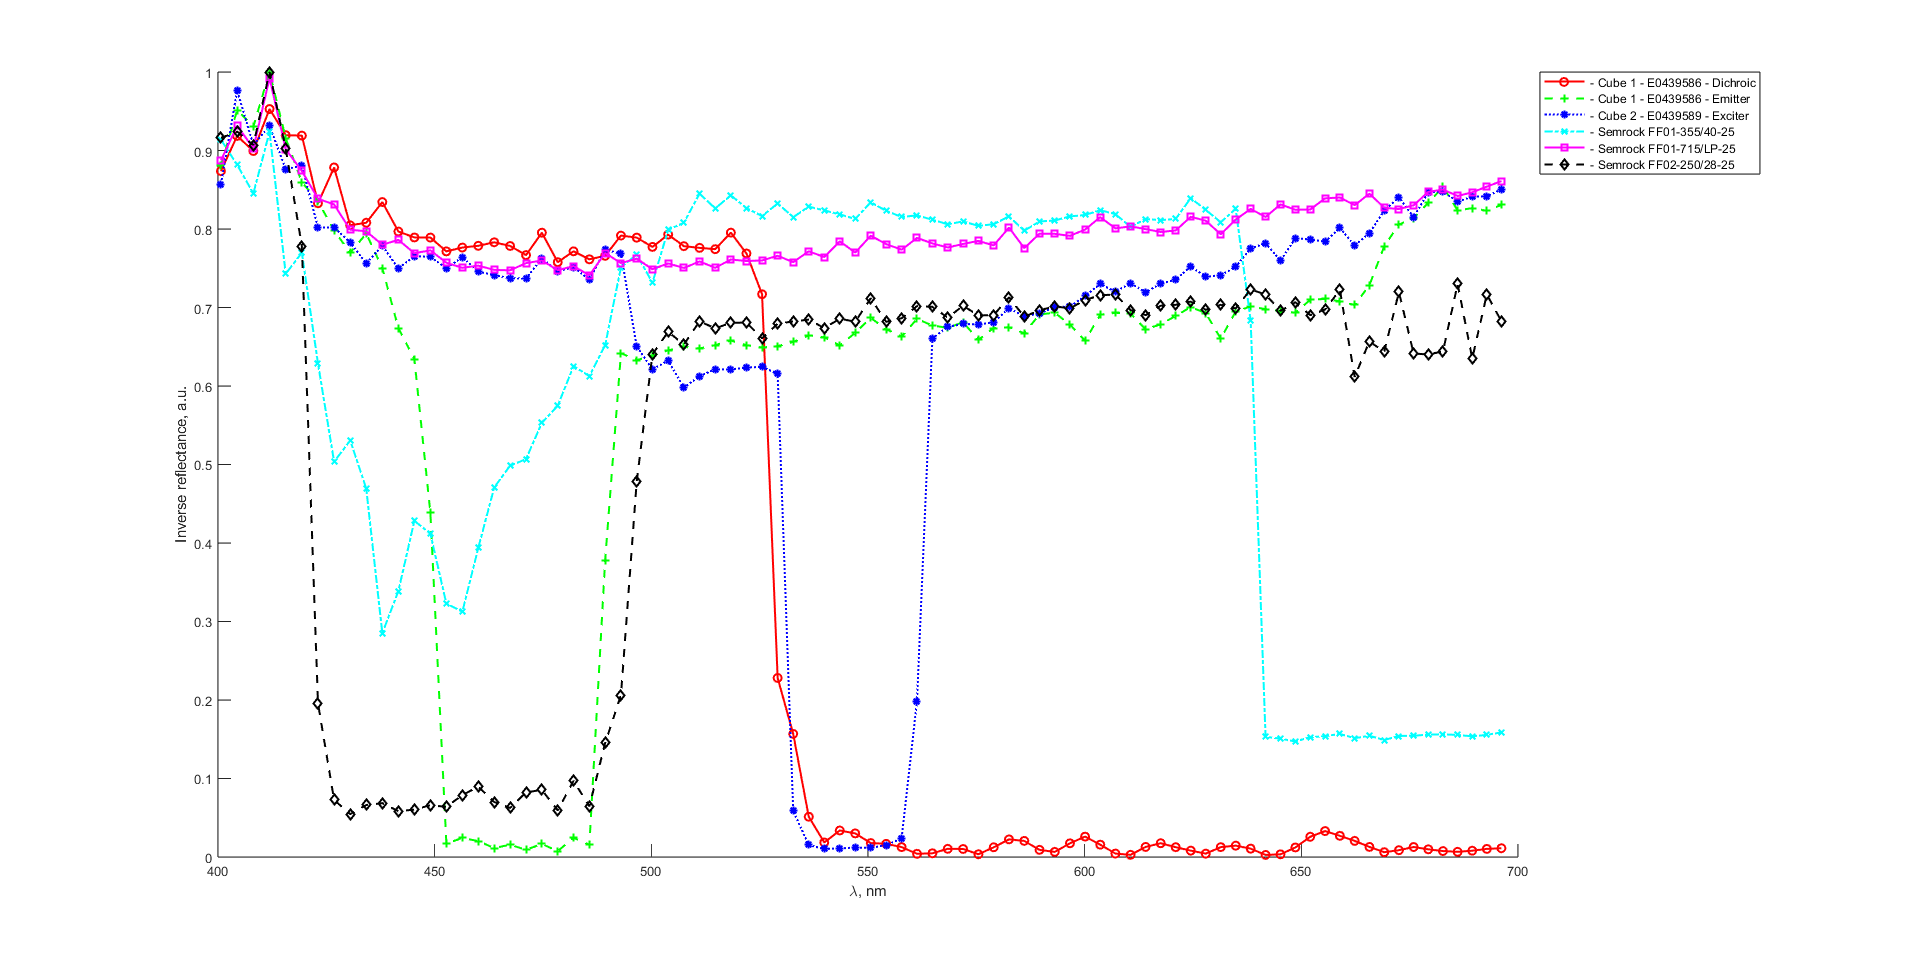

f = figure('WindowState','maximized');
hold on
set(f, 'Visible', 'on');
xlabel('\lambda, nm');
ylabel('Inverse reflectance, a.u.');
idx=1;
nth = 10; % plot every nth data point
%set(f,'Color','c')
for idx=1:size(filelist)
    nameval = lineprops(idx); % Utilise lineprops.m file for unique B&W-compatible marker styles.
    plot(data(idx).spectrum{:,"Wavelength_Nm"}(161:nth:1000),data(idx).spectrum{:,"Intensity_A_u_"}(161:nth:1000), nameval{:},'LineWidth', 1.5)
    %xlim([400, 700]);
    %ylim([0, 200]);
end
lgnd = legend({data.name},"Location",'bestoutside');
exportgraphics(f,rootdir+"\Combined Plot.png",'Resolution',300);
savefig(f,rootdir+"\Combined Plot.fig")
hold off

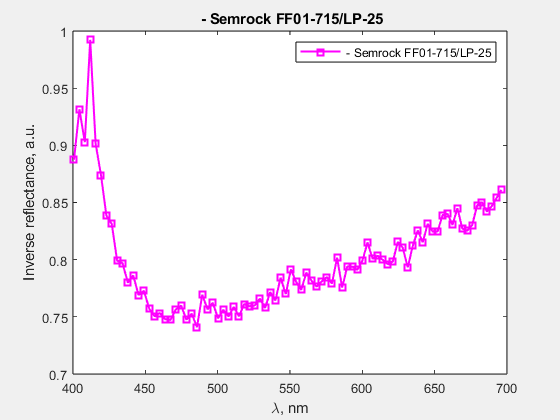

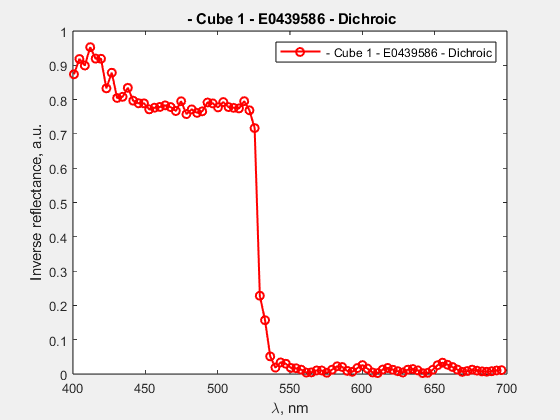

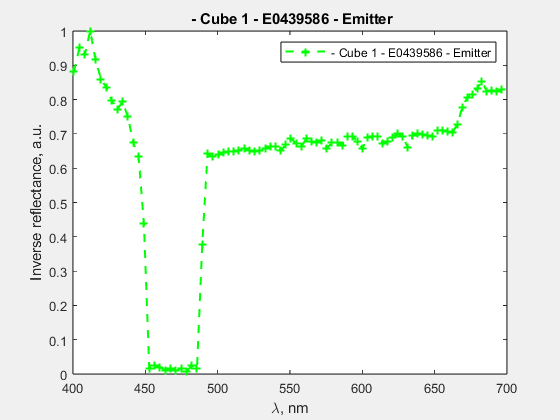

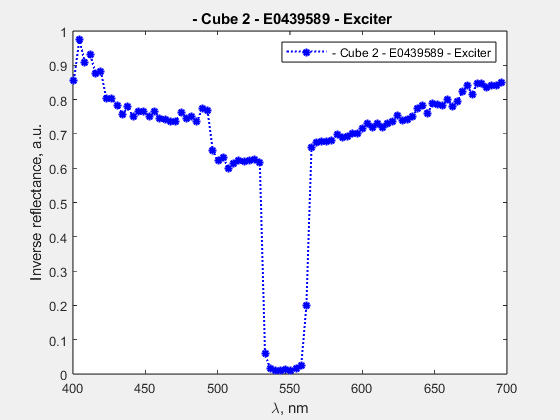

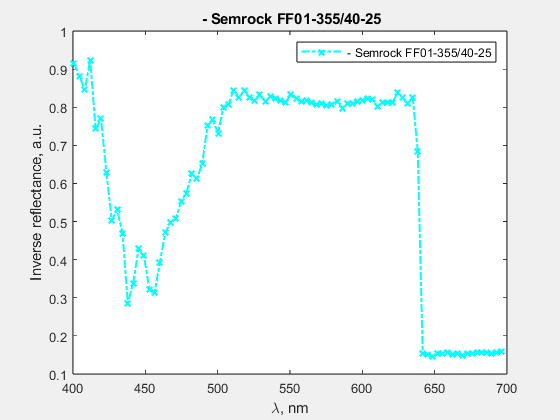

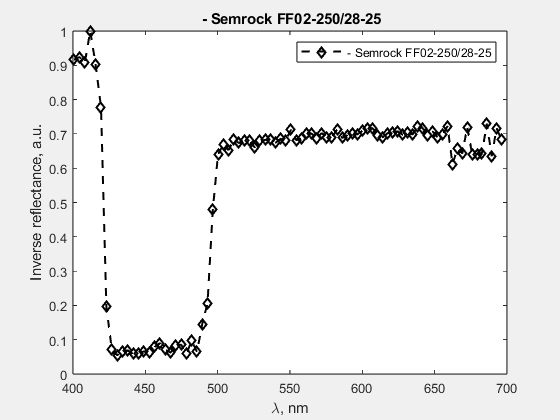

idx=1;
for idx=1:size(filelist)
    fInd(idx) = figure(idx+1);
    set(fInd, 'Visible', 'on','WindowState','normal');
    %plot(data(idx).spectrum{:,"Wavelength_Nm"}(1:50:end),data(idx).spectrum{:,"Intensity_A_u_"}(1:50:end),...
     %   nameval{:},'LineWidth', 1.5)
    nameval = lineprops(idx);
    % Plot every 10th data point
    plot(data(idx).spectrum{:,"Wavelength_Nm"}(161:10:1000),data(idx).spectrum{:,"Intensity_A_u_"}(161:10:1000), nameval{:},'LineWidth', 1.5)
    lgnd = legend((data(idx).name));
    title({data(idx).name});
    xlabel('\lambda, nm');
    ylabel('Inverse reflectance, a.u.');
    exportgraphics(fInd(idx),filelist(idx).folder+"_every10th_pt.png",'Resolution',300);
    savefig(fInd(idx),filelist(idx).folder+"_every10th_pt.fig")
end

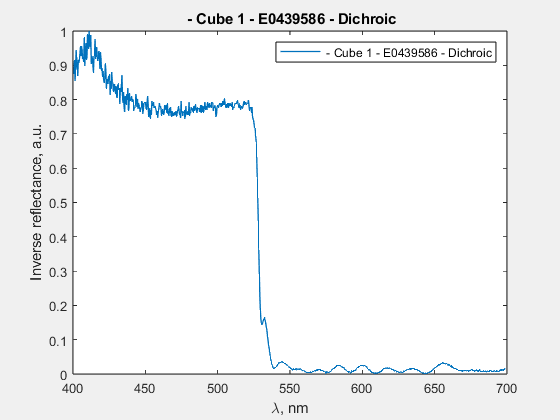

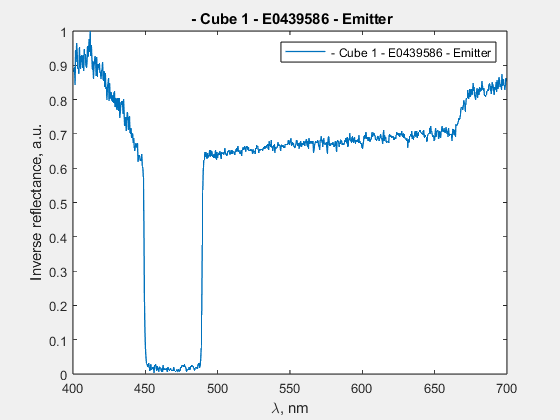

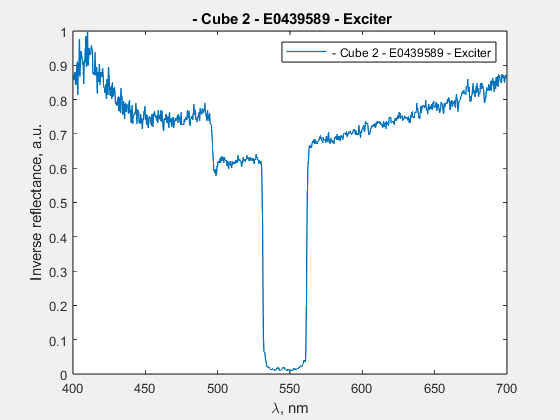

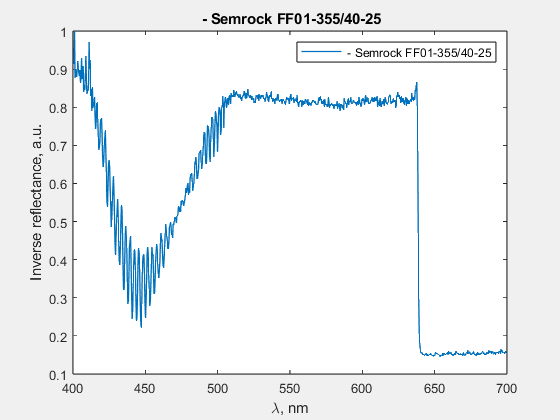

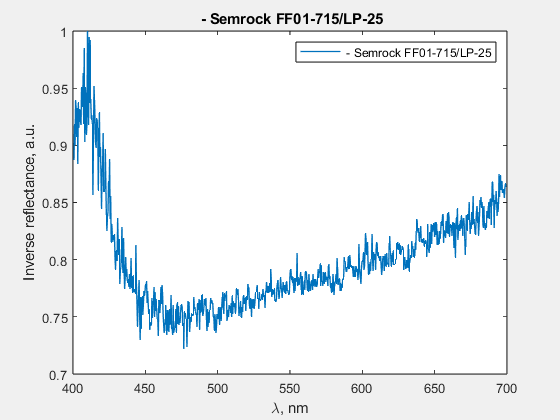

idx=1;
for idx=1:size(filelist)
    % Plot all data points
    fFull(idx) = figure(idx+size(filelist,1)+1);
    set(fFull, 'Visible', 'on');
    plot(data(idx).spectrum{:,"Wavelength_Nm"}(161:1000),data(idx).spectrum{:,"Intensity_A_u_"}(161:1000), 'LineWidth', 1)
    %xlim([400, 700]);
    %ylim([0, 200]);
    lgnd = legend((data(idx).name));
    title({data(idx).name});
    xlabel('\lambda, nm');
    ylabel('Inverse reflectance, a.u.');
    exportgraphics(fFull(idx),filelist(idx).folder+"_full.png",'Resolution',600);
    savefig(fFull(idx),filelist(idx).folder+"_full.fig")
end

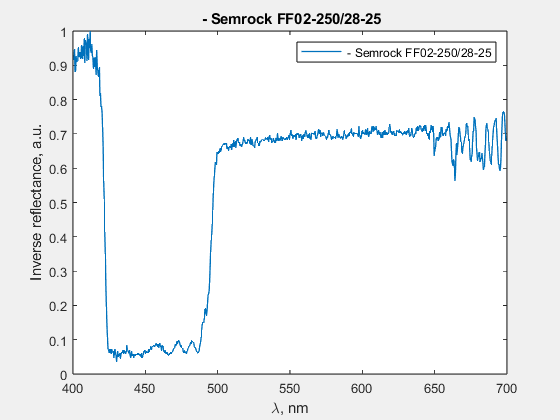


hold off